# Lesson 9

Written by Brenda So, Cory Nezin and Guy Bar Yosef

## Objective

After this class, you should be able to:

- Understand how to simiulate stochastic processes

- Understand linear regression and how to implement it

# Random Process

Although often confusing for people at first, a random process is simply a function of two variables: time and the result of a random experiment. 

As a contrived example, imagine flipping a coin, where at each discrete flip you will sample from either a sinewave if the coin lands on heads or a cosine wave if the coin lands on tails. This set-up can be viewed in two ways: 

- If the coin toss (the random experiment) is fixed, then you simply get a deterministic signal (sinewave or cosine wave).

- If time is fixed, you get a random variable (in this case a coin toss). This view is the reason that a random process is often also described as a collection of random variables- as you index over time, you get many (infinit!) random variables.

A random process is also called a stochastic process.

# INTRODUCTION TO STOCHASTICITY

Electrical engineers often use MATLAB to simulate random process, and the reason that it is so popular is that a lot of problems in EE are stochastic problems. Examples:

- What happens when there's random noise in a communication channel?

- What is the probability of corrupting a signal to the point that it cannot be recovered? 

Today, we are going to explore the idea of randomness with case studies. We are first going to show simple examples of stochastic processes, and will then conclude with a more elaborate exploration of stochasticity in communication channels.

## EXAMPLE 1 : MONTY HALL

The classic monty hall problem -- do you switch the door or not. Let's find out.

Let's run a simulation to experimentally see the results. Assume there are two contestants, the first of which never switchs and the second of which always switches. 

We can simulate this problem in several ways. The laziest is to first assume that the contestants always choose door 1. The first contestant, in row 1, will only win if the car is behind that door. The second contestant, will always switch doors. The door that is opened is always empty, so the second contestant will only lose if the car is behind door 1.

N = 50000; % number of simulations

prize_door = unidrnd(3,1,N); % map out the prize-doors for all simulations

result = zeros(2,N);
result(1, prize_door == 1) = 1;
result(2, prize_door ~= 1) = 1;

win_rate = cumsum(result, 2);
x = 1:1:N;
win_rate = win_rate ./ x;

Plotting the results:

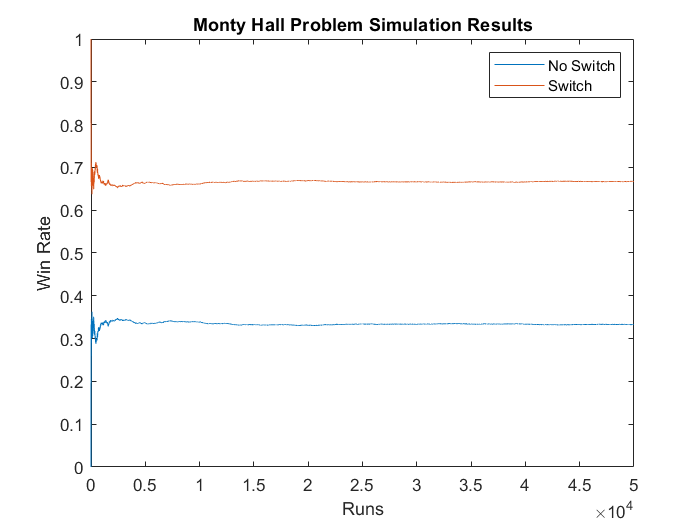

figure;
plot(x, win_rate(1,:), 'DisplayName','No Switch');
hold on;
plot(x, win_rate(2,:), 'DisplayName', 'Switch');
legend('show');
title('Monty Hall Problem Simulation Results'), xlabel('Runs'), ylabel('Win Rate');
hold off;

## EXAMPLE 2 : St. Petersburg Paradox

A casino offers a game in which a fair coin is tossed repeatedly until the first heads comes up, for a total of t+1 tosses. The casino will pay out $2^t$ dollars. In this game t is the number of tosses landing on tails before a heads appears.

Let's see how much money you are going to get if you play the game:

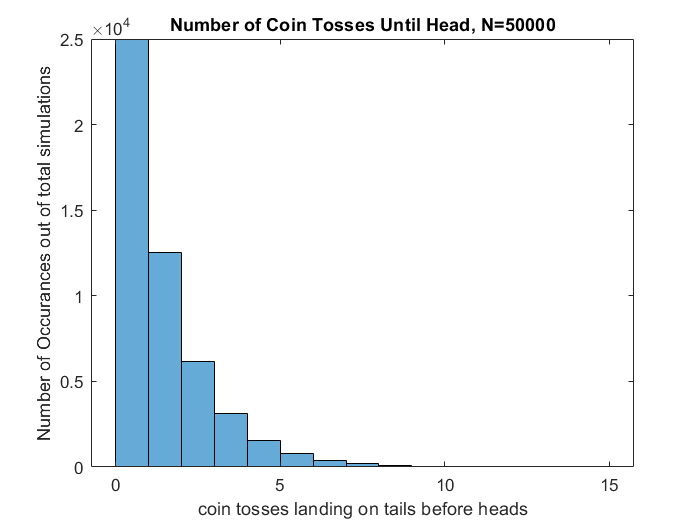

N = 50000; % number of simulations
num_tosses = zeros(1,N);
for i = 1:N
   toss = randi([0,1]);
   while (toss ~= 0)
      num_tosses(i) = num_tosses(i) + 1;
      toss = randi([0,1]);
   end
end

figure;
histogram(num_tosses, unique(num_tosses))
title(['Number of Coin Tosses Until Head, N=', num2str(N)]);
xlabel('coin tosses landing on tails before heads');
ylabel('Number of Occurances out of total simulations');

What is the expected value of playing this game?


$$$ E[Game] = \frac{1}{2}2^0 + \frac{1}{4}2^1 + \frac{1}{8}2^2 + \frac{1}{16}2^3 + \cdots = \sum_{n=0}^{\infty}\frac{1}{2^{n+1}}2^n =  \sum_{n=0}^{\infty}\frac{1}{2} = \infty$$


Seems like a pretty good deal to me!

Okay, now what if instead of paying $2^t$ for any t, the casino cuts off the payout after a certain threshold $t_0$, making all $t>t_0$ have a payout of $2^{t_0}$.


$$E[Game] = \sum_{n=0}^{t_0}\frac{1}{2^{n+1}}2^{n} + \sum_{n=t_0}^{\infty}\frac{1}{2^{n+1}}2^{t_0} = \sum_{n=0}^{t_0}\frac{1}{2} + \sum_{n=t_0}^{\infty}2^{t_0 - n - 1}$$


We can apply a change of variables on the second sum and get the overall result of:


$$\frac{1}{2}(t_0) + \sum_{n=0}^{\infty}\frac{1}{2^{n+1}} = \frac{1}{2}(t_0) + \Bigg[ \sum_{n=0}^{\infty}\frac{1}{2^{n}} \Bigg] - \frac{1}{2^{0}}  \\

= \frac{1}{2}(t_0 ) + \Bigg[ 1+1 \Bigg]  - 1  = \frac{1}{2}(t_0 + 2) $$


Hmm, it appears that if we take the possibility (however unlikely it was to begin with) of having an infinite amount of tails before a heads as a payout, the expected value shrinks down considerably (infinitely, one could argue).

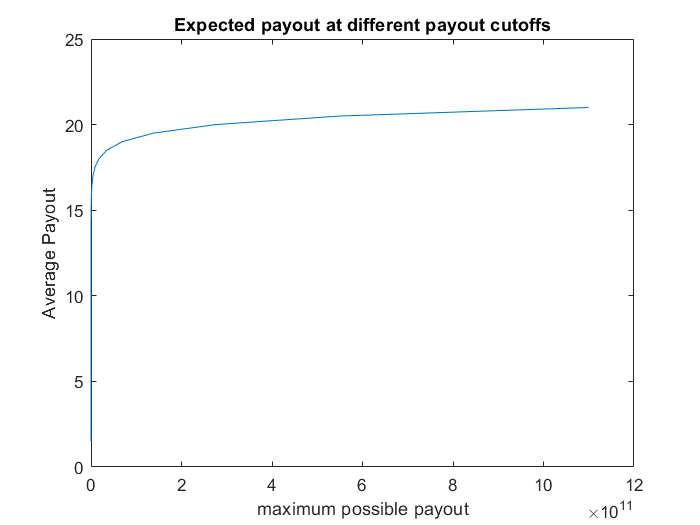

t0 = 1:1:40;
max_payout = 2.^(t0);

expected_payout = (1/2)*(t0+2);

figure;
plot(max_payout, expected_payout);
title('Expected payout at different payout cutoffs');
xlabel('maximum possible payout'), ylabel('Average Payout')

- This provides an interesting analysis, because although the expected value of the original problem was inifinity, it appears as though an average joe or jane wouldn't be interested in paying more than 20-ish dollars to participate.

## EXAMPLE 3 : The Birthday Pardox

Not a stochastic process, but a fun probabily simulation regardless.

What are the chances of, among a group of people, at least two having the same birthday?

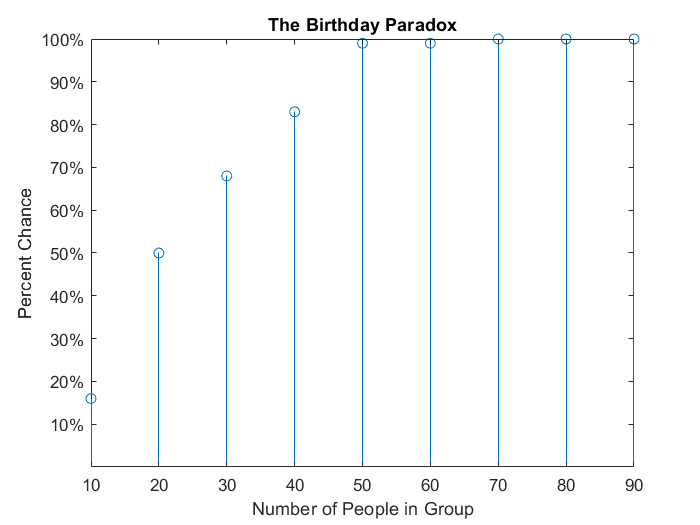

N = 100; % number of simulations per number of people

num_of_people = [10 20 30 40 50 60 70 80 90];
birthday_percent = zeros(1,9);

for i = 1:9
    cur_sum = 0;
    for j = 1:N
        generated_group = round(rand(1, num_of_people(i))*365);
        
        if length(generated_group) ~= length(unique(generated_group))
            cur_sum = cur_sum + 1;
        end
    end
    birthday_percent(i) = cur_sum/100;
end

stem(birthday_percent);
title("The Birthday Paradox")

xlabel("Number of People in Group")
xticks(1:9)
xticklabels({'10', '20', '30', '40', '50', '60', '70', '80', '90', '100'})

ylabel("Percent Chance")
yticks(0.1:0.1:1.0)
yticklabels({'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'})